**Dear Students, **

**Welcome to Lab 1 - Part 2!**

**In this lab, we will explore implementation techniques of the convolution sum.  **

#### **Note: **

- **In this notebook, you are expected to (i) write or/and complete code snippets (ii) write your observations and inferences based on the results of the code. You can write your answers inferences just after the question where ANSWER is mentioned. **

- **If you feel that some information is missing for carrying out your exercises, you can assume them appropriately. Please remember to state your assumptions.  If you find typos in the notebook, please let us know.  **

**You are expected to submit the solved notebook by 24th October 2020, 11.59pm. **

### **References: **

- **https://classroom.google.com/u/0/w/MTUyODczMTg4NDQ2/tc/MTU1MDg5NDgyMjY5**

# **Slow and Fast Convolutions (100 Points)**

## **Learning Outcome**: 

At the end of this lab exercise, you will be able to implement the convolution operation to compute the output of a system given an input sequence and the impulse response of the system, using two different techniques. The technique we will explore are:

- Direct or Slow Convolution

- Fast Convolution 

## Background:

In the theory part, you studied about 4 ways of representing a linear time-invariant  (LTI) system [1, 4]. They are

- Impulse response, denoted by $h[n]$

- Frequency response, denoted by $H(e^{j\omega})$

- System function (Z-transform), denoted by $H(z
)$

- Linear Constant Coefficient Difference Equation, which is $y[n] = - \sum_{k=1}^Na_k y[n-k] + \sum_{k=0}^M b_kx[n-k]$. 

Each one of the above representations play a vital role in design and/or implementation of digital systems (such as filters). 

In this lab, we will talk about implementation of a system with finite impulse response (FIR) by convolving the input sequence with the impulse response of the system. 

## Direct or Slow Convolution:

In an FIR filter, we have, $h[n]\geq 0, \text{for}\; N_1\leq n \leq N_2
$ and $h[n] = 0
$ otherwise. For simplicity, let us assume, $N_1 = 0
$ and $N_2 = L_h-1
$. Such a filter is called as an $L_h$-length FIR filter. Now, given an input sequence, $x[n]$, of length $L_x$ (what does it mean?),  we can compute the output sequence by the following convolution sum:  

                                                          $y[n] =  \sum_{k=0}^{L_h-1}h[k]x[n-k]$ for $n\in \mathbb{Z}$  

It is interesting to note that the above convolution sum has the form of the following LCCDE, $y[n] =  \sum_{k=0}^{L_h-1}b_kx[n-k]$, where $b_k = h[k]$ for $k=0,\ldots, L_h-1$. The above approach of computing convolution by direct evaluation of the convolution sum is called the Direct or Slow Convolution. The reason why it is called as the "Slow" convolution will be clear at the end of the notebook.

Let us write some code to implement this convolution.

### **Coding Question 1 (10 Points): **

- Generate the impulse response, $h[n]$, of a causal moving average filter of an arbitrary length, $L_h$. 

Lh= 11;  %we take an arbitrary length 11
h= ones(1,Lh)/Lh %Moving average filter of length Lh

h =     0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909


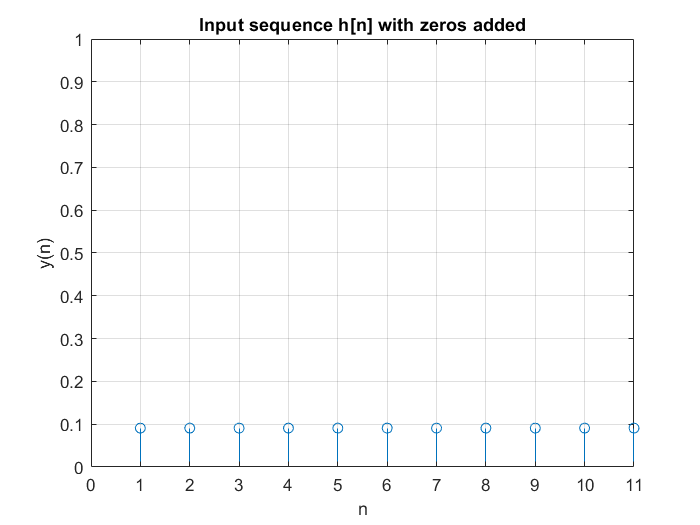

h1=1:1:Lh;%limit of sequence h(n) of length Lh
stem(h1,h)
xlabel('n')
ylabel('y(n)')
axis([0 11 0 1]);
title('Input sequence h[n] with zeros added')
grid on;

% Write your code here

- Generate a discrete-time sequence, $x[n]$ of an arbitrary length, $L_x$. 

Lx=20;
%We generate a unit step sequence
x= ones(1,Lx) 

x =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


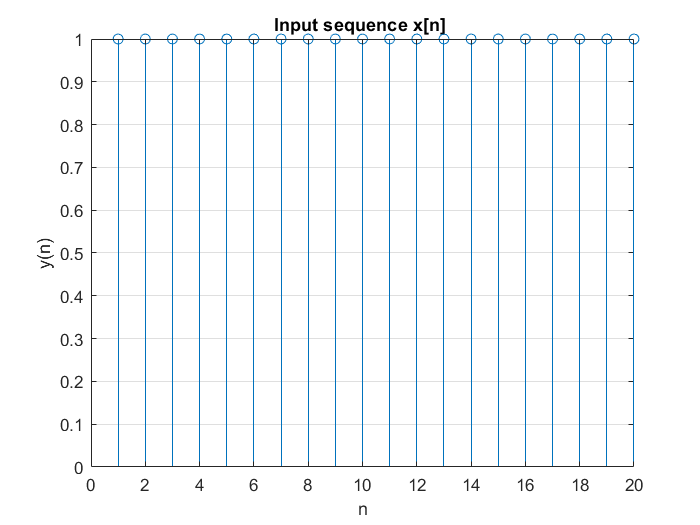

x1=1:1:Lx; %limit of sequence x(n) of length Lx=20
stem(x1,x)
xlabel('n')
ylabel('y(n)')
title('Input sequence x[n] ');
grid on;

% Write your code here

- Compute $y[n] = h[n]\ast x[n]$by evaluating the convolution sum. 

%Taking some parameters for result
Ly=Lx+Lh-1; %y will have length of 20+11-1= 30
outl=1:1:Ly; %limit of output sequence y(n)
X=[x,zeros(1,Lh-1)]  %making x of length Lx+Lh=30 by adding additional zeros in end to ensure values are in bound upto index 31

X =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0


H=[h,zeros(1,Lx-1)]  %making h of length Lx+Lh=30 by adding additional zeros in end to ensure values are in bound upto index 31

H =     0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


%CONVULATION
for i=1:Ly
    Y(i)=0;  %To add the result of individual terms.
    for j=1:Lx
        if((i-j+1)>0)
        Y(i)=Y(i)+(X(j)*H((i+1)-j));
        end
    end
end
disp('Convolution result is :');

Convolution result is :


Y

Y =     0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9091    0.8182    0.7273    0.6364    0.5455    0.4545    0.3636    0.2727    0.1818    0.0909


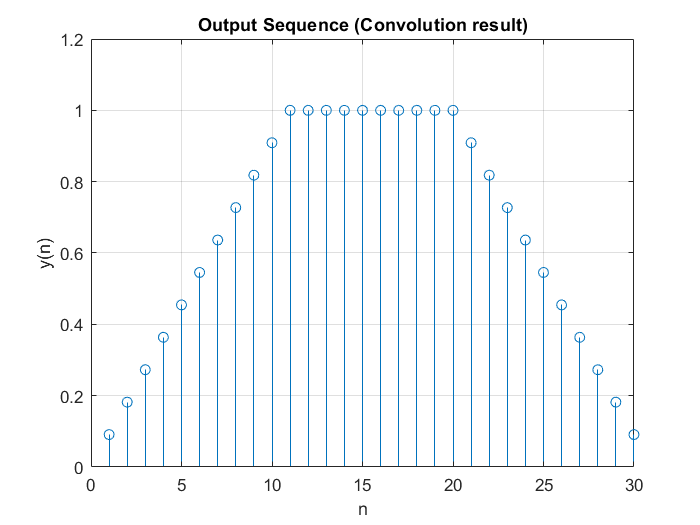

stem(outl,Y)
xlabel('n')
ylabel('y(n)')
title('Output Sequence (Convolution result)')
grid on;

% Write your code here

- Verify your answer using the inbuilt Matlab function, [conv](https://in.mathworks.com/help/matlab/ref/conv.html). 

disp("convolution result using conv function is :")

convolution result using conv function is :


Ych=conv(x,h)

Ych =     0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9091    0.8182    0.7273    0.6364    0.5455    0.4545    0.3636    0.2727    0.1818    0.0909


if Ych==Y
    disp("same result with inbuilt function ");
else disp("result did not match");
end

same result with inbuilt function 


% Write your code here

### **Inference 1 (10 Points): **

- What is the maximum length of $y[n]$ over which it can be non-zero? Express your answer in terms of $L_h~\text{and} ~L_x$.

            ANSWER: The maximum length over which y[n] can be non zero  is Lh+Lx-1.( which is its length too, ie. 30 in example)

- In order to compute $y[n_0]$, how many and which all samples of the input sequence $\{x[n]\}$ are required? What is the buffer memory requirement to store them? 

            ANSWER: if $y[n_0]$ mean the first sample of{y[n]} then we need only the first sample from {x[n]}. For any other $n_i$ we need i 

                                samples from 1 to i. So buffer memory required to store them is 1 if we need to calculate only first sample , i for 

                                 i th sample.

- Which kind of buffer would you use for the above convolution operation? (Hint: [https://en.wikipedia.org/wiki/Circular_buffer,](https://en.wikipedia.org/wiki/Circular_buffer,) [https://www.dspguide.com/ch28/2.htm](https://www.dspguide.com/ch28/2.htm))

            ANSWER:I would use circular buffer as that can get reloaded with newer values as I proceed calculating different term of 

                            convolution.

## **Fast Convolution: **

Noting that discrete-time Fourier transform (DTFT) of $h[n]\ast x[n]$ is equal to $H(e^{j\omega})X(e^{j\omega})$, where $H(e^{j\omega}) = \text{DTFT}(h[n])$and $X(e^{j\omega}) = \text{DTFT}(X[n])$, we can consider the following approach for computing the convolution sum to obtain $y[n]$:

- Compute $H(e^{j\omega})$ and $X(e^{j\omega})$

- Obtain $Y(e^{j\omega})  =  H(e^{j\omega})X(e^{j\omega})$

- Compute the inverse DTFT of $Y(e^{j\omega})
$ to obtain $y[n]$. 

If we are able to do the above operations more efficiently than the direct computation of the convolution sum, we could adopt this approach. We will explore this in the below. 

Let us code a bit. 

### **Coding Question 2 (10 Points):**

- Compute and plot the DTFT of $h[n]$ you generated above, over $0\leq \omega <2\pi$.  

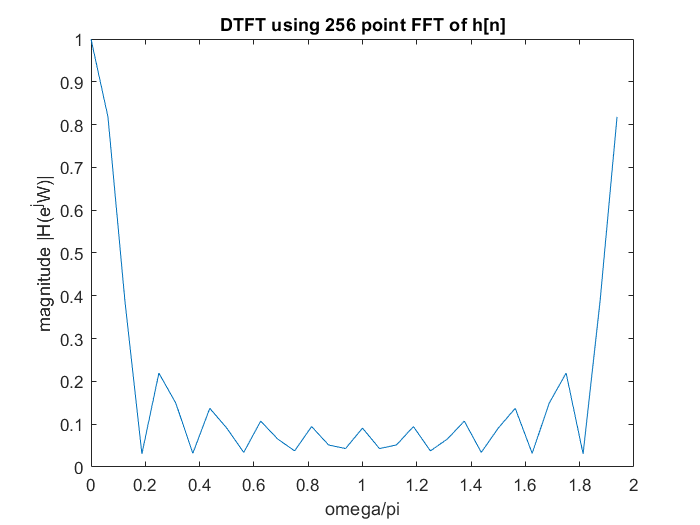

N = 32; %N point FFT (32 point ) as we have to take it greater than 11. We can't recover h[n] correctly for N<11.
X = fft(h, N); %we use FFT to get DTFT
omega = 2*pi * (0:(N-1)) / N; %To convert the N of FFT to omega of DTFT
plot(omega/pi, abs(X))
title("DTFT using 256 point FFT of h[n]");
xlabel("omega/pi");
ylabel("magnitude |H(e^jW)|")

% WRITE YOUR CODE HERE. 


### **Coding Question 3 (10 Points):**

- Write a code snipped to reconstruct $h[n]$ from the DTFT you have computed

hrecovered=ifft(X,N)  %Recovering signal from FFT using IFFT .

hrecovered =     0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000   -0.0000         0    0.0000         0         0         0         0         0   -0.0000         0         0


hrecovered=hrecovered(1:11)  %removing zero padding to get h[n] (of length 11)

hrecovered =     0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909


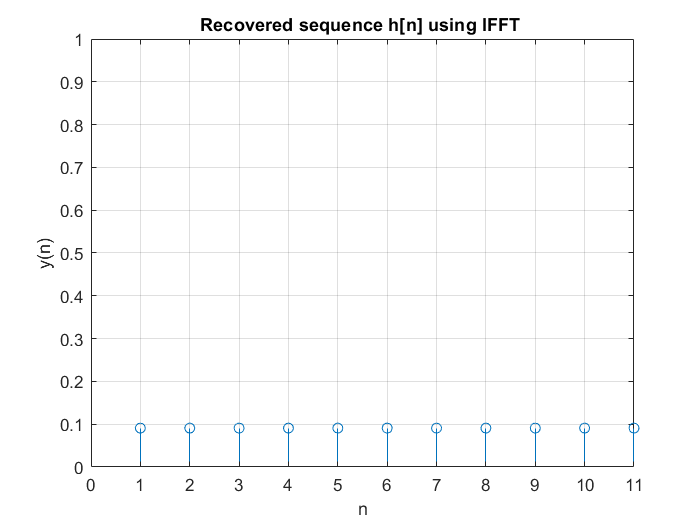

length(hrecovered) ;  %now its same length as h[n]
stem(h1,hrecovered)
axis([0 11 0 1]);
title('Recovered sequence h[n] using IFFT ')
xlabel('n')
ylabel('y(n)')
grid on;

% WRITE YOUR CODE HERE. 

### Inference 2 **(10 Points):**

- Were you able to reconstruct $h[n]$ from $H(e^{j\omega})$? Why? Why not? 

            ANSWER: Yes , I could sucessfully recover and reconstruct h[n] from $H(e^{j\omega})$ as I took 32 point DFT while 32>length(h[n]).

- Which parameters in your code affect the reconstructability? 

            ANSWER: If we take FFT of less than 11 point we will not be able to recover h[n] from it. For sucessful recovery N $\ge$length(h[n]) which is 11 in here.

As you might have noted, one of the main challenges with adopting the above approach is that computing the DTFT in a digital computer is not possible as $\omega
$ is a continuous variable representing the digital frequency.  One way to deal this problem is by using the approach you have just used!  That is, by computing DTFT values at closely (usually uniformly) spaced sample values of $\omega
$, i.e., at $-\pi, -\pi+\delta\omega, \pi+2\delta\omega, \ldots, \pi-\delta\omega, \pi$ or at $0,  \delta\omega, 2\delta\omega, \ldots, 2\pi-\delta\omega, 2\pi$ (Recall that it is sufficient to compute the DTFT function only over a period of length$2\pi$.)  However, we should be careful with this approach in that, we should select $\delta \omega$ such that we are able to reconstruct $x[n] $from the sampled DTFT.  Let us assume that $\delta \omega =  \frac{2\pi}{N}$, where, we need to select $N$ such that we are able to recover/reconstruct inverse DTFT values without loss of information [2]. We will find such an $N$in the following. 

Assume a discrete-time sequence $x[n], -\infty<n<\infty$ and consider its DTFT  $X(e^{j\omega})$ at $\omega = \frac{2\pi}{N}k, \;\; k = 0,\ldots, N-1.$We have, 

                                                             $X\left(\frac{2\pi k}{N}\right) = \sum_{n=-\infty}^{\infty}x[n]e^{-j2\pi k n/N}},  k=1,\ldots, N-1.$ for $k=0,\ldots, N-1$.

Noting that $e^{-j2\pi k(n+mN)/N} = e^{-j2\pi kn/N} $for any integer $m$, we can re-arrange the above equation as follows:

                              
$$X\left(\frac{2\pi k}{N}\right) =\ldots+\sum_{n=-N}^{-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$
  
$$+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$
  
$$\sum_{n=N}^{2N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\ldots
$$
 
$$+\ldots
$$
  
$$=\sum_{l=-\infty}^{\infty} \sum_{n=l N}^{l N+N-1} x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$


    Changing the index in the inner summation from $n $ to $n-lN$ and changing the order of the summation, we have, 

                                                                 $X\left(\frac{2\pi k}{N}\right) =\sum_{n=0}^{N-1}   \left[\sum_{l=-\infty}^{\infty} x[n-l N] \right]e^{-j2\pi k n/N}}$ for $k=0,\ldots, N-1.$

Let $x_{p} [n] = \sum_{l=-\infty}^{\infty} x[n-l N]$for $n\in \mathbb{Z}$. 

Let us write a quick code snippet to visualize $x_p[n]$. Let $x[0] = 0, x[1] =0.25, x[2] =0.5, x[4]=0.75, x[5]=1$and $x[n]=0$ for all other values of $n$. 

### **Coding Question 4 (5 Points):**

Write a code to generate and plot $x_p[n]$ for an arbitrary value of $N.$

N = [8];   % Assume a value of N
x = [0, 0.25, 0.5 0.75 1]; % given sequence
c=1:1:length(x)

c =      1     2     3     4     5


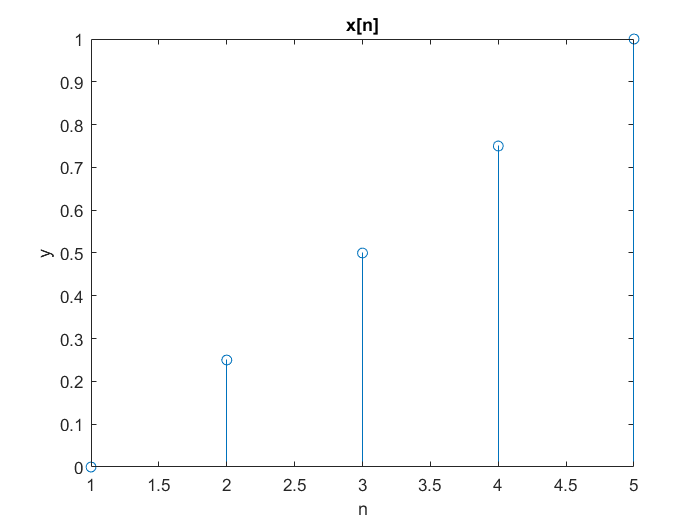

stem(c,x)
xlabel("n")
title("x[n]")
ylabel("y")

x_p=[]


x_p =

     []



x_N=[x,zeros(1,N-length(x))]   % making x[n] of length 8 for further computations by zero padding

x_N =          0    0.2500    0.5000    0.7500    1.0000         0         0         0


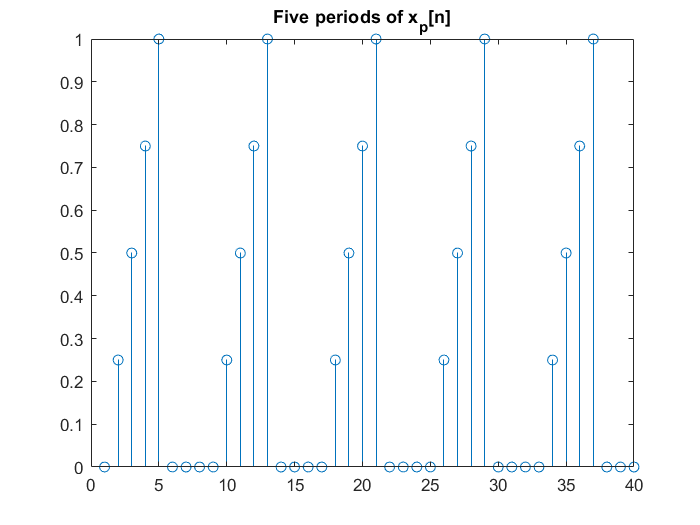

d=1:1:5*length(x_N); %To plot 5 periods of x_p[n]
for i=-1000:1000  %To stimulate sum from -infinity to  infinity approximately
    x_p= [x_p x_N];   %constructing x_p
end
stem(d,x_p(1:40))
title("Five periods of x_p[n]")

% it goes on repeating to infinity
% WRITE A CODE SNIPPET TO PLOT x_p[n]

### **Inference 3 (5 Points):**

- Is $x_p[n]$ is a periodic signal? If yes, what is its fundamental period?  

            ANSWER: Yes $x_p[n]$ is periodic with fundamental period N which is 8 here.

- What should be the relationship between $L_x$ and $N$to be able to get back $x[n]$ from $x_p[n]$?

            ANSWER: N$\ge \;$$L_x$ to be able to get back x[n] from $x_p[n]$

You might have got them right! $x_p[n]$is a periodic sequence with period $N$. Hence, you can express it using Fourier series as follows: 

                                                    $x_p[n] = \sum_{k=0}^{N-1}c_k e^{j2\pi k n/N}$ for $n = 0, \ldots, N-1$, 

where $c_k = \frac{1}{N}\sum_{n=0}^{N-1}x_p[n]e^{-j2\pi kn/N}$ for $k=0,\ldots, N-1$. Note that $c_k=\frac{1}{N}X\left(\frac{2\pi k }{N}\right) $ for $k=0,\ldots, N-1. $

This implies that 

$x_p[n] = \frac{1}{N}\sum_{k=0}^{N-1}X\left(\frac{2\pi k}{N}\right)e^{j2\pi k n/N}$ for $n = 0,\ldots, N-1$. 

The above equation helps in reconstruction of the periodic $x_p[n]$ from the samples of $X(e^{j\omega})$taken at $w = 2\pi k/N$. However, we want to get $x[n]$, not $x_p[n]$!

### **Theory Question 1 (0 Points):**

How and when can we get back $x[n]$ from $X\left(\frac{2\pi k}{N}\right)$values at $k=0,\ldots, N-1$? (Hint: use your Inference 3). 

Note that we can recover, $x[n]$ from $x_p[n]$ when $N \geq L_x$, i.e., when there is no *time-domain aliasing. * In other words, the smallest value of $N$required to get back $x[n]$ is $L_x$. 

The above sampled $X(e^{j 2 \pi k/N})$is called as the $N$-point DFT and denoted simply by $X[k]$. 

Hence, we have the following DFT and IDFT pair for a sequence $x[n]$ with $N \geq L_x$. 

                                                $N$**-point DFT:   **$X[k] = \sum_{n=0}^{N-1}x[n]e^{-j2\pi kn/N}$for $k=0,\ldots, N-1$

                                                $N$**-point IDFT:  **$ x[n] = \frac{1}{N}\sum_{k=0}^{N-1}X[k]e^{j2\pi k n/N}$for $n = 0,\ldots, N-1$. 

Let us now implement the following now. 

### **Coding Question 4 (10 Points):**

- Compute and plot $4$-point DFT and $100-$point DFT of the sequence, $x[n] = [1, 1, 1, 1]$. Plot them in the same figure. You need to think about how you will compute $100
$-point DFT of a sequence of length $4$(Hint: use zero-padding for the last 96 positions to generate a $100
$-point sequence from $x[n]$)

- Compare your answer with the Matlab inbuilt function, [fft](https://in.mathworks.com/help/matlab/ref/fft.html)

clear y;
x=[1 1 1 1];
N=4;
l4=1:1:N ; %values of s to plot 4 point DFT 
%4 point DFT
for k=0:N-1   %function for N point DFT
    for n = 0:N-1;
        y(n+1) = x(n+1).*exp(-(j*2*pi*k*n)/N);
    end
    X4dft(k+1)= sum(y);  %result for 4 point DFT
end
disp("4 point DFT by code")

4 point DFT by code


X4dft  %To display it

X4dft =     4.0000    1.0000    1.0000    1.0000


disp("4 point DFT by inbuilt function fft")

4 point DFT by inbuilt function fft


X4f=fft(x,4)   %4 point DFT using inbuilt function

X4f =      4     0     0     0



x100=[x,zeros(1,100-length(x))]; %zero padding to get signal of length 100
%100 point DFT
N=100;
l100=1:1:N ; %values of s to plot 100 point DFT
for k=0:N-1   %function for N point DFT
    for n = 0:N-1;
        y(n+1) = x100(n+1)*exp(-(j*2*pi*k*n)/N);
    end
    X100dft(k+1)= sum(y);  %result for 100 point DFT
end
disp("100 point DFT by code")

100 point DFT by code


X100dft

X100dft =     4.0000    1.3887    1.0881    1.0236    1.0066    1.0019    1.0005    1.0002    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


disp("100 point DFT by inbuilt function fft")

100 point DFT by inbuilt function fft


X100f=fft(x100,100) %100 point fft using inbuilt function

X100f =    4.0000 + 0.0000i   3.9724 - 0.3755i   3.8905 - 0.7421i   3.7564 - 1.0913i   3.5739 - 1.4150i   3.3479 - 1.7058i   3.0845 - 1.9575i   2.7909 - 2.1649i   2.4749 - 2.3241i   2.1448 - 2.4328i   1.8090 - 2.4899i   1.4761 - 2.4960i   1.1543 - 2.4531i   0.8512 - 2.3644i   0.5737 - 2.2346i   0.3277 - 2.0691i   0.1179 - 1.8745i  -0.0521 - 1.6578i  -0.1802 - 1.4267i  -0.2657 - 1.1885i  -0.3090 - 0.9511i  -0.3122 - 0.7214i  -0.2782 - 0.5061i  -0.2114 - 0.3110i  -0.1167 - 0.1411i   0.0000 + 0.0000i   0.1325 + 0.1096i   0.2742 + 0.1864i   0.4187 + 0.2302i   0.5596 + 0.2421i   0.6910 + 0.2245i   0.8077 + 0.1805i   0.9054 + 0.1144i   0.9804 + 0.0308i   1.0305 - 0.0648i   1.0543 - 0.1670i   1.0515 - 0.2700i   1.0232 - 0.3684i   0.9712 - 0.4570i   0.8986 - 0.5314i   0.8090 - 0.5878i   0.7068 - 0.6231i   0.5967 - 0.6355i   0.4839 - 0.6238i   0.3734 - 0.5884i   0.2702 - 0.5302i   0.1788 - 0.4515i   0.1032 - 0.3551i   0.0467 - 0.2448i   0.0118 - 0.1248i



stem(l4,X4dft)
hold on 
stem(l100,X100dft)
title("4 and 100 point DFT of x[n]")
xlabel("n")
ylabel("y(n)")
% Write your code here. 

- Now, plot the DTFT of $x[n]$ for $\omega\in [-\pi, \pi]$, based on your DFT coefficients. (see [fftshift](https://in.mathworks.com/help/matlab/ref/fftshift.html))

x4dtft=fftshift(x,4) %4 point DTFT

x4dtft =      1     1     1     1


x100dtft=fftshift(x100,100) %100 point DTFT

x100dtft =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


N=4;
%l4=(-N/2+1):1:N/2 ;
N=100;
%l100=(-N/2+1):1:N/2 ;
stem(x4dtft)
hold on 
stem(x100dtft)
title("4 and 100 point DTFT of x[n]")
xlabel("n")
ylabel("y(n)")
hold off
% Write your code here. 

### Inference 4 **(10 Points):**

- What are your observations? 

Recall that we wanted to obtain the sequence $y[n]$. We have developed a way to compute a Fourier Transform and its inverse, namely DFT and IDFT of a discrete sequence in a digital computer. Now, can we compute DFTs of $h[n]$ and $x[n]$ to obtain $H[k]$ and $X[k]$, respectively, multiply them and take the IDFT of the result to get $y[n]? $

For answering the above question, recall the following from your Signals and Systems class:

Assume that  $H[k]$ and $X[k]$ are $M$-point DFT of $h[n]$ and $x[n]$, respectively. Then, 

                                                                  $\tilde{y}[n] = M\text{-Point IDFT}(X[k]H[k]) = \sum_{k=0}^{M-1}h[k][x[(n-k)_M]$, for $n = 0,\ldots, M-1$

where $(n-k)_M$ is the modulo $M$value of $(n-k)$which will take a value in $\{0,1, \ldots, M-1\}$. 

The above operation is called the circular *convolution *and it is usually denoted by $\otimes$, i.e., the $M$-point circular convolution of  $h[n]$ and $x[n]$,  $h[n]\otimes x[n] = \sum_{k=0}^{M-1}h[k][x[(n-k)_M]$. 

### Coding Question 5 **(10 Points):**

- Generate $h[n]$ and $x[n]$ of lengths $L_h$ and $L_x$, respectively. 

- Compute $M$-point circular convolution of them. 

- Compute $H[k]$ and $X[k]$,  $M$-point DFTs of $h[n]$ and $x[n]$, respectively for an arbitrary value of $M$. 

- Multiply them to obtain $\tilde{Y}[k]$ and compute its $M$-point IDFT to obtain $\tilde{y}[n]$. 

- Compare your answer with the directly computed convolution above and also by using the  inbuilt Matlab function, [ccnv](https://in.mathworks.com/help/signal/ref/cconv.html). 

x = [1 2 -1 1]; %x[n] of length 4
h = [1 1 2 1 0 2 1 1]; %h[n] of length 8
Lx=length(x)

Lx = 4

Lh=length(h)

Lh = 8

Mptidftf = cconv(x,h)

Mptidftf =     1.0000    3.0000    3.0000    5.0000    1.0000    3.0000    6.0000    1.0000    3.0000         0    1.0000



% Write your code here. 

### **Inference (10 Points):**

- For what values of $M$, are $y[n]$ and $\tilde{y}[n]$ will be the same? 

            ANSWER:

Under the above condition on $M$, we can obtain the output $y[n]$using the above technique. Such a technique of obtaining the convolution sum of two finite-length sequences, using the DFT and IDFT operations is called as the *fast convolution. *You may be wondering why it would be fast, as it seems to involve more number of steps than with the *direct convolution * used earlier. However, it turns out that when the DFT and IDFT are computed using any of a large class of algorithms called Fast Fourier Transforms (FFT), fast convolution is more efficient (faster) than the direct convolution.  Hence, the fast convolution is a very important signal processing tool [3]. Can you think of some advantages of direct convolution over the fast convolution? 

ANSWER: When we only need to get one term of the DFT or DTFT and not the entire sequence direct convolution may give the answer faster as then we don't do too many multiplications(including complex ones )  while in fft algorithm we have to do some minimum number of multiplications even if we are finding only a term of DFT(say first term).

# Practical Experiment (50 Points) 

Now, record your voice or some music for $5
$ seconds to obtain $x[n]$ and filter it using the low-pass filter of length M (which you should choose):   

- Speak and record your voice or music for 5 seconds (see [audiorecorder](https://in.mathworks.com/help/matlab/ref/audiorecorder.html) and[ https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering](https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering))

%x =  [];    % Write a code snippet to record your voice or some music for 5 seconds and store it in x as an one-dimensional vectors
rec = audiorecorder(4000,8,1); %to ensure shorter recorded signal.
disp('Start')

Start


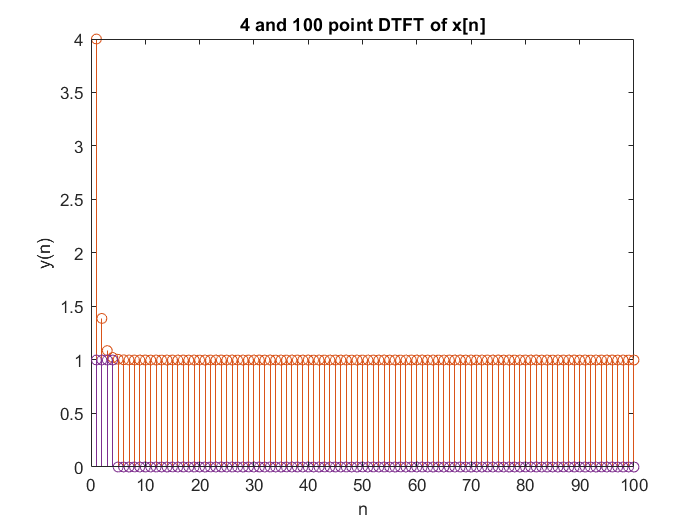

recordblocking(rec, 5);

disp('End');

End


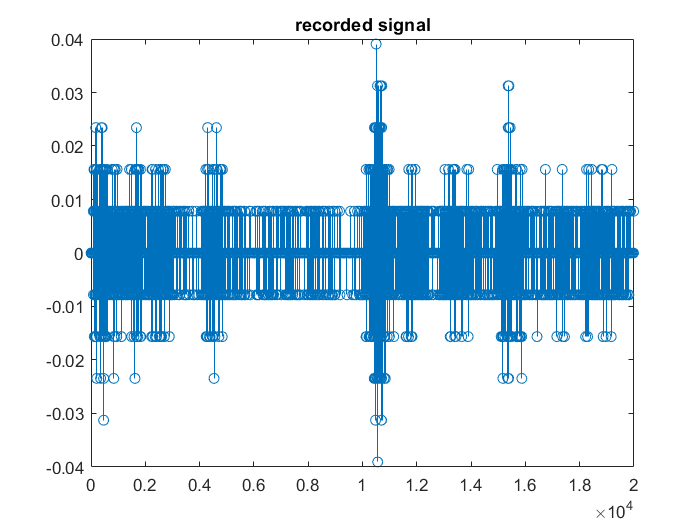

X = getaudiodata(rec);
stem(X)
title("recorded signal")

- Now, using [fft](https://in.mathworks.com/help/matlab/ref/fft.html), roughly find the frequency components in your recorded $x$. 

Xfreq=(fft(X));

stem(Xfreq)%  plotting the fft

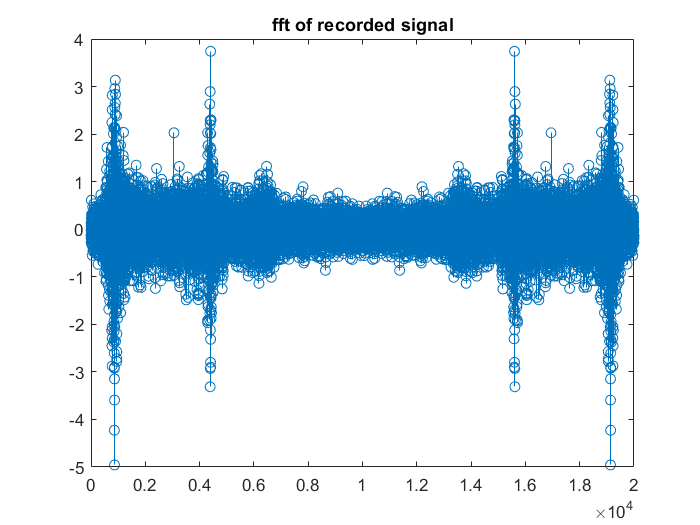

title("fft of recorded signal")

Xfreqs=fftshift(Xfreq)

Xfreqs =   -0.0313 + 0.0000i
   0.1467 + 0.1462i
   0.0318 - 0.2489i
   0.1121 - 0.0611i
  -0.0262 + 0.2093i
   0.0100 + 0.2162i
   0.1645 + 0.1319i
  -0.1923 - 0.0552i
  -0.2118 - 0.0103i
   0.0917 + 0.1135i


stem(Xfreqs)

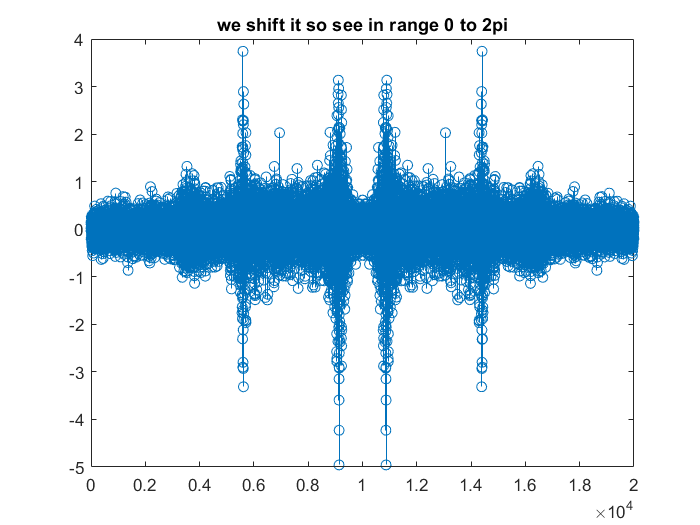

title("we shift it so see in range 0 to 2pi")

% Write your code here

- Now, in order to remove frequencies greater than 3000 Hz components in $x[n]$, design $h[n]$, by finding appropriate $M$.

M = [3000]

M = 3000

h  = (1/M)*ones(1,M) 

h = 	1.0e+-3 *

    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333


h=[zeros(1,length(Xfreq)/2-1500),h,zeros(1,(length(Xfreq)/2-1500))] %To make it same sength as signal with stopping frequencied outside 3000 HZ

h = 	1.0e+-3 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


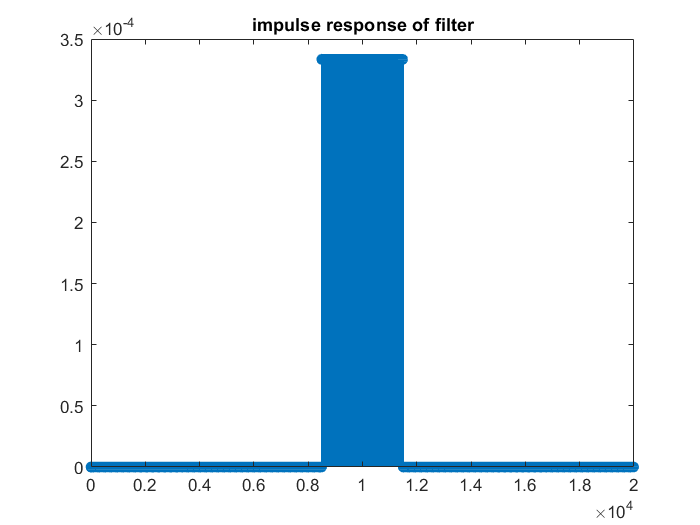

stem(h)
title("impulse response of filter")

- Now filter $x[n]$using $h[n]$ and display the output as a plot and sound:

filtered = h.*Xfreq;    % Filtering x using the filter with impulse response h
stem(filtered);

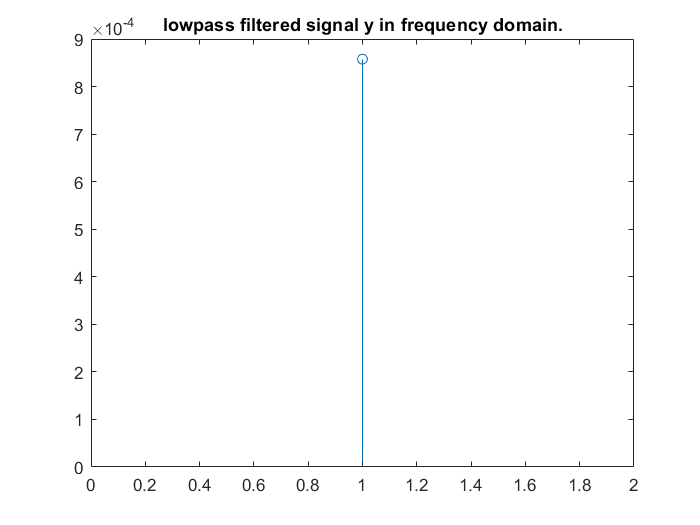

plot(filtered);
title("lowpass filtered signal y in frequency domain.");

% Plot the output y
yt=ifft(filtered);
stem(yt)
title("Lowpass Filtered (<3000Hz) signal y in time domain");
% Plot y in frequency domain
sound(real(filtered))
pause(1);
% Output y on your speaker


- Make observations and write down in the below: 

            ANSWER: 

# (Optional) Convolution and Correlation:

** Note: This part of the code will accounted for your grading**

One more very important operation, similar to the convolution is correlation. Between any two sequences, $x[n]$ and $y[n]$, it is defined as follows:

                                                                           $r_{xy}[l]=\sum_{n=-\infty}^{+\infty}x[n]y[n-l]$.

**Question: **

- How are the convolution  of $x[n]$ and $y[n]$ and correlation of $x[n]$ and $y[n]$ related? 

Let us write some code: 

### Coding Question **(10 Points):**

- Generate a sequence $x[n]$

- Generate another sequence, $y[n] = 0.75x[n-D]$

- Compute the correlation between these two sequences. 

             % Write your code here. 

### Inference **(10 Points):**

- Is there any relationship between $r_{xy}[l]$ and $D$? Comment. 

            ANSWER:

- What does the correlation of two sequences signify? Think of applications where you can use the correlation operation to find out important parameters (Hint: Note that $D$ is the delay). 

             ANSWER:

## Other References

- [https://allsignalprocessing.com/](https://allsignalprocessing.com/)

- John G. Proakis and D.G. Manolakis, Digital Signal Processing: Principles, Algorithms and Applications, Prentice Hall, Fourth Edition.

- L.R. Rabiner and B. Gold, Theory and Application of Digital Signal Processing, Prentice Hall, 1992. 

- A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall, 3rd Edition.